# Estudio de curva TPV

## Plan de vuelo

clear; clc

v = 1.8;

%             t   x  y  z  vx vy vz
way_data = [ 00  00 00 00  00 00 00
             10  00 05 10  00  v 00
             20  05 10 10   v 00 00 
             30  10 10 00  00 00 00 ];

time_step = 0.001;

waypoints = Waypoint.empty;
for i = 1:size(way_data,1)
    waypoints(i) = Waypoint();
    waypoints(i).t = way_data(i,1);
    waypoints(i).setPosition(way_data(i,2:4));
    waypoints(i).setVelocity(way_data(i,5:7));
end
fp  = FlightPlan(2,waypoints);
fp.mode = "TPV";

## Visualización

### Posición instantánea

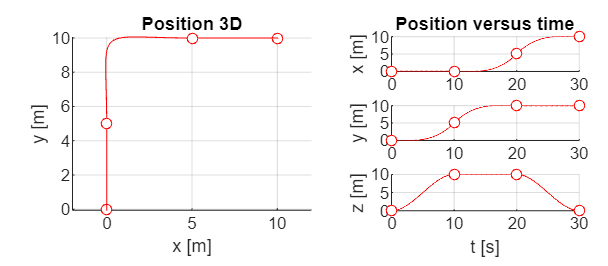

fp.routeFigure(time_step,'r')

En esta ocasión podemos ver segmentos curvos entre waypoints consecutivos. La trayectoria completa es derivable. Una aeronave puede seguirla con precisión.

### Velocidad instantánea

También podemos mostrar la velocidad instantánea del plan de vuelo.

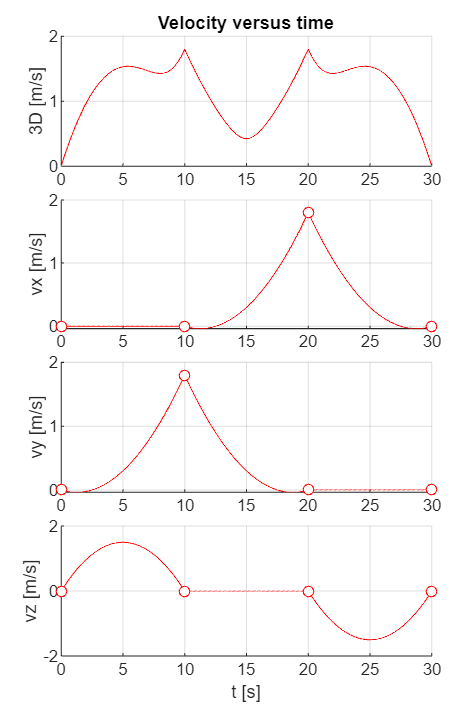

fp.velocityFigure(time_step,'r')

En esta ocasión sí se muestra la información explícita de velocidad indicada en los waypoints.